%read data
path2a = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Aburatsubo_1933-1940_hour.xlsx";
path2b = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Aburatsubo_2001-2020_hour.xlsx";
path3a = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Ito II_1973-1980_hour.xlsx";
path3b = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Ito II_2011-2020_hour.xlsx";
path5a = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Onisaki_1961-1970_hour.xlsx";
path5b = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Onisaki_2011-2020_hour.xlsx";

[time2a, SL2a] = readGauge(path2a);
[time2b, SL2b] = readGauge(path2b);
[time3a, SL3a] = readGauge(path3a);
[time3b, SL3b] = readGauge(path3b);
[time5a, SL5a] = readGauge(path5a);
[time5b, SL5b] = readGauge(path5b);

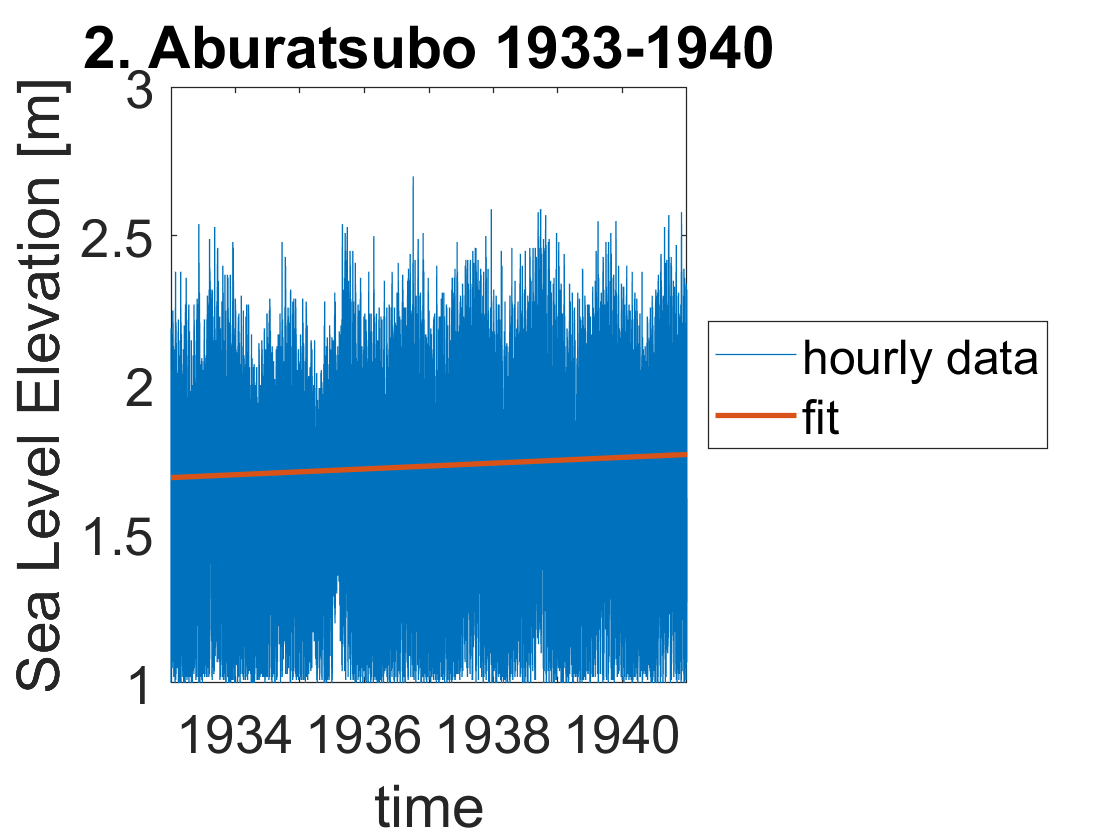

SLR for gauge 2. Aburatsubo 1933-1940 from 01/01/1933 to 12/31/1940 is 0.97046 cm/y.


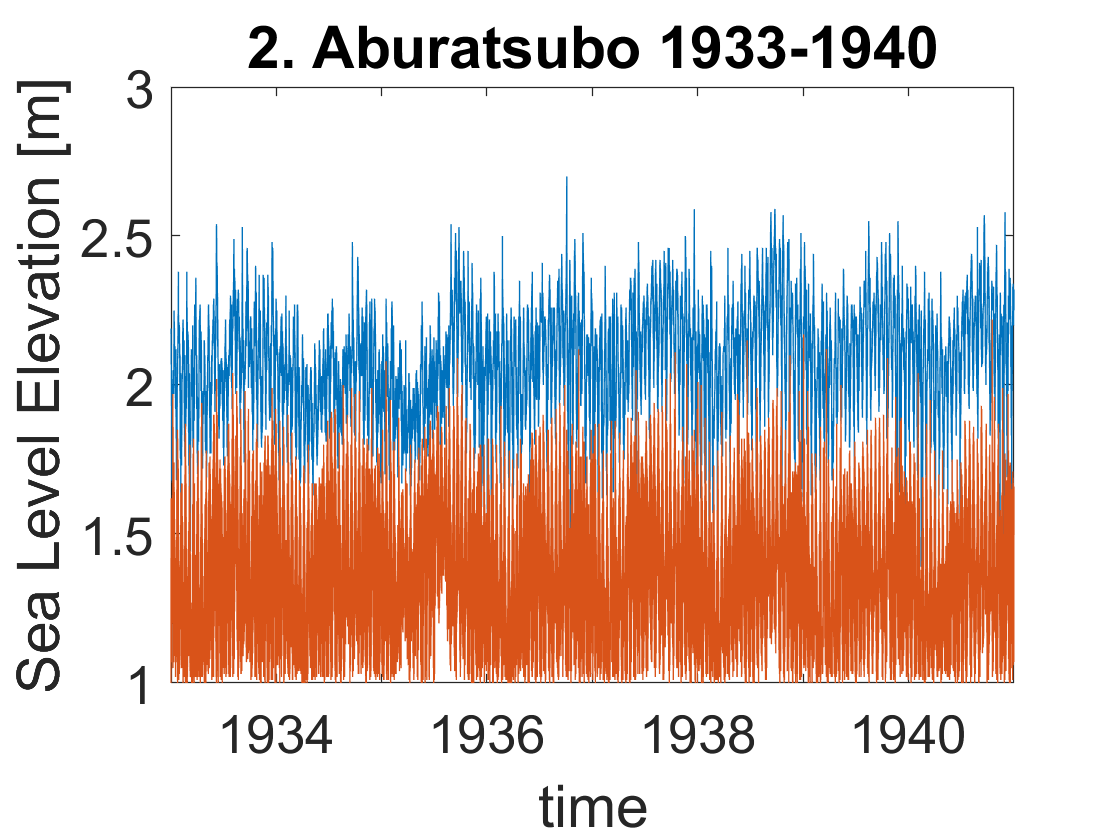

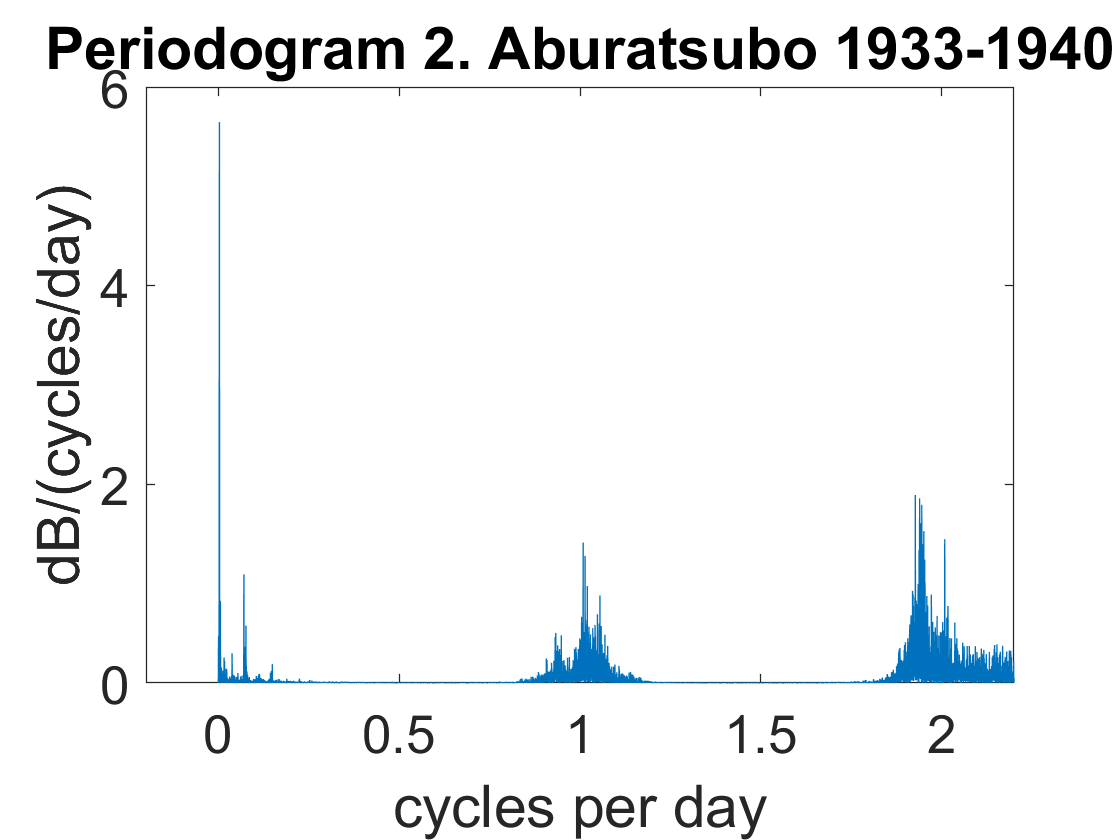

%2. Aburatsubo 1933-1940
%datum is 5m

[regsol2a, peaks2a, mins2a, peaks_loc2a, mins_loc2a] = analyze(time2a, SL2a, '2. Aburatsubo 1933-1940');

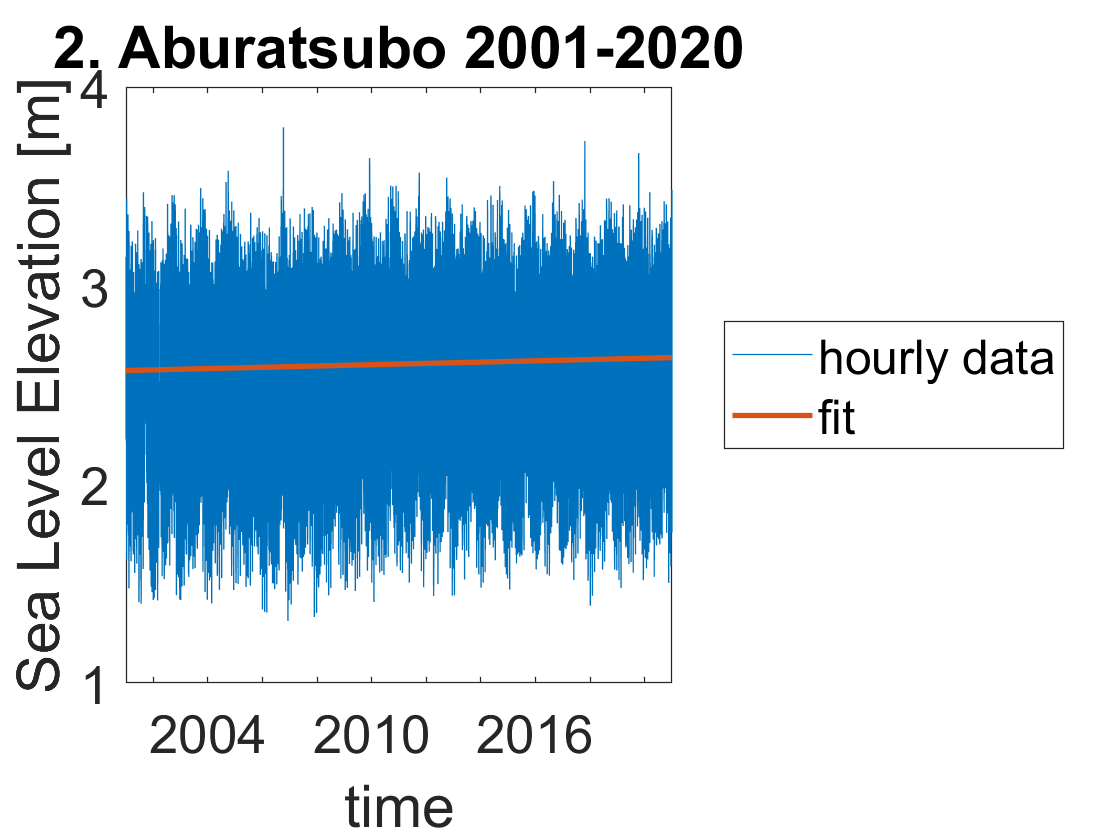

SLR for gauge 2. Aburatsubo 2001-2020 from 01/01/2001 to 12/31/2020 is 0.32476 cm/y.


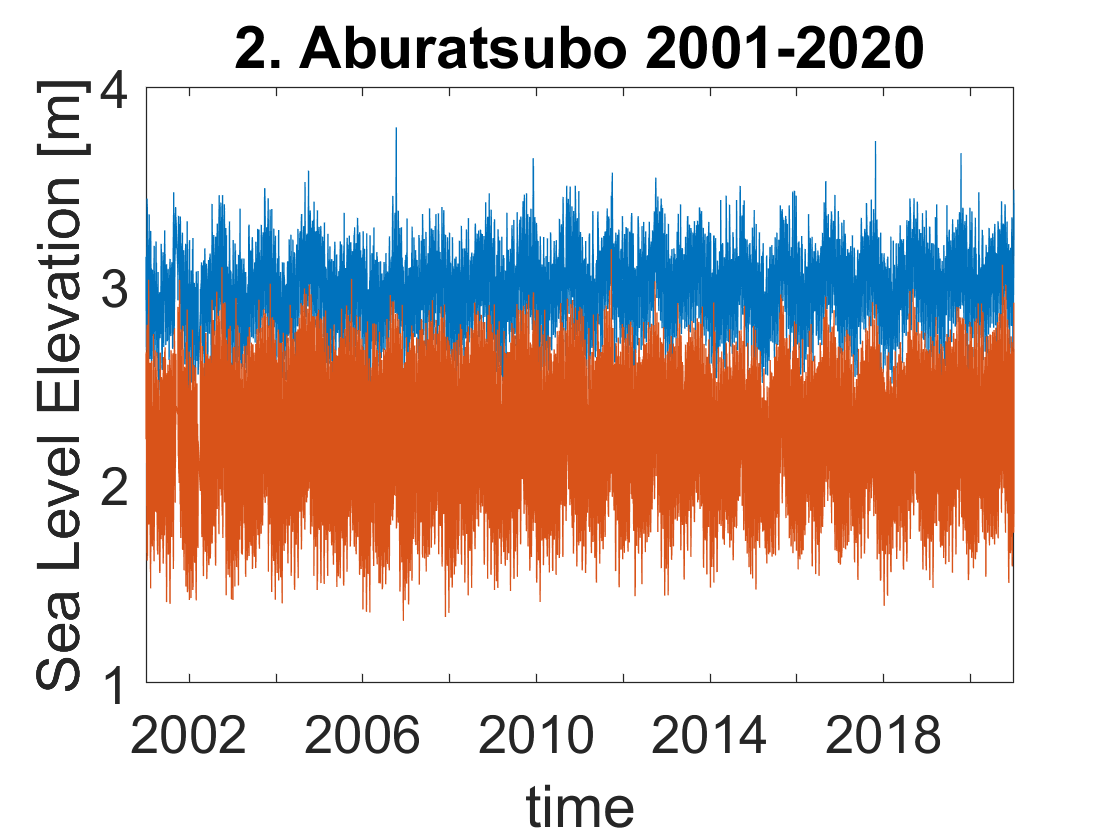

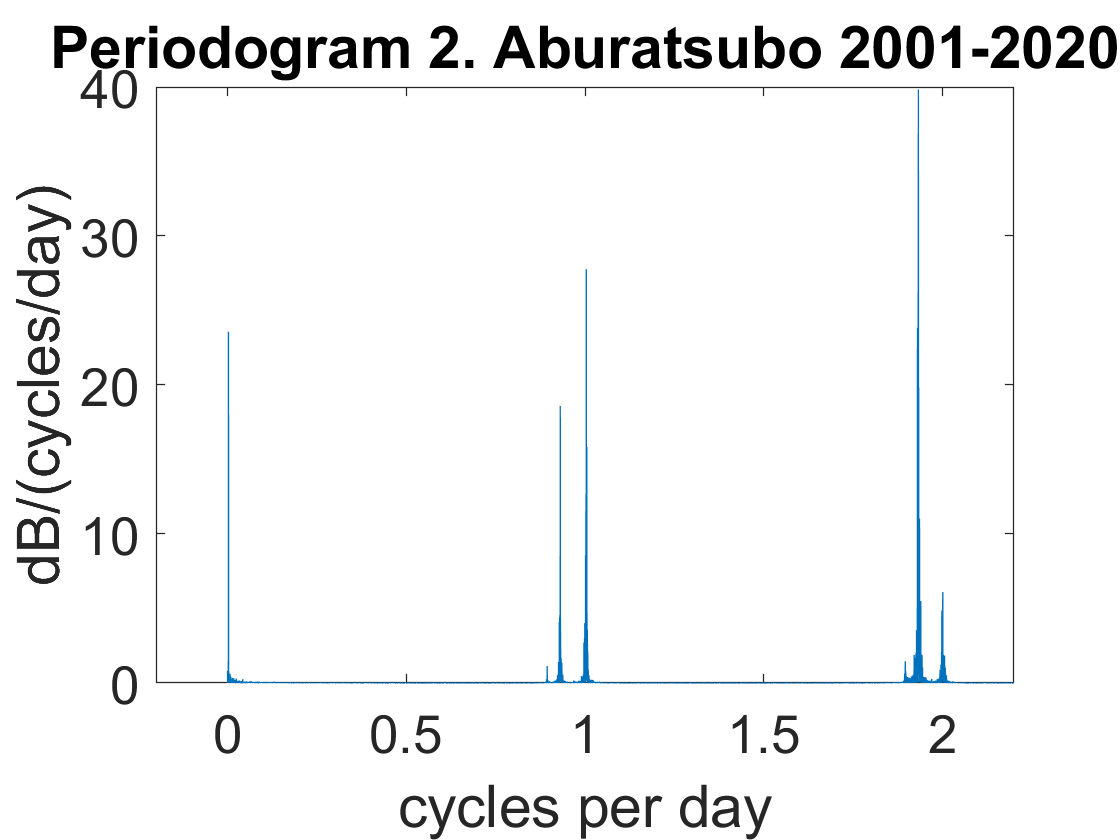

%2. Aburatsubo 2001-2020
%datum is 5m

[regsol2b,  peaks2b, mins2b, peaks_loc2b, mins_loc2b] = analyze(time2b, SL2b, '2. Aburatsubo 2001-2020');

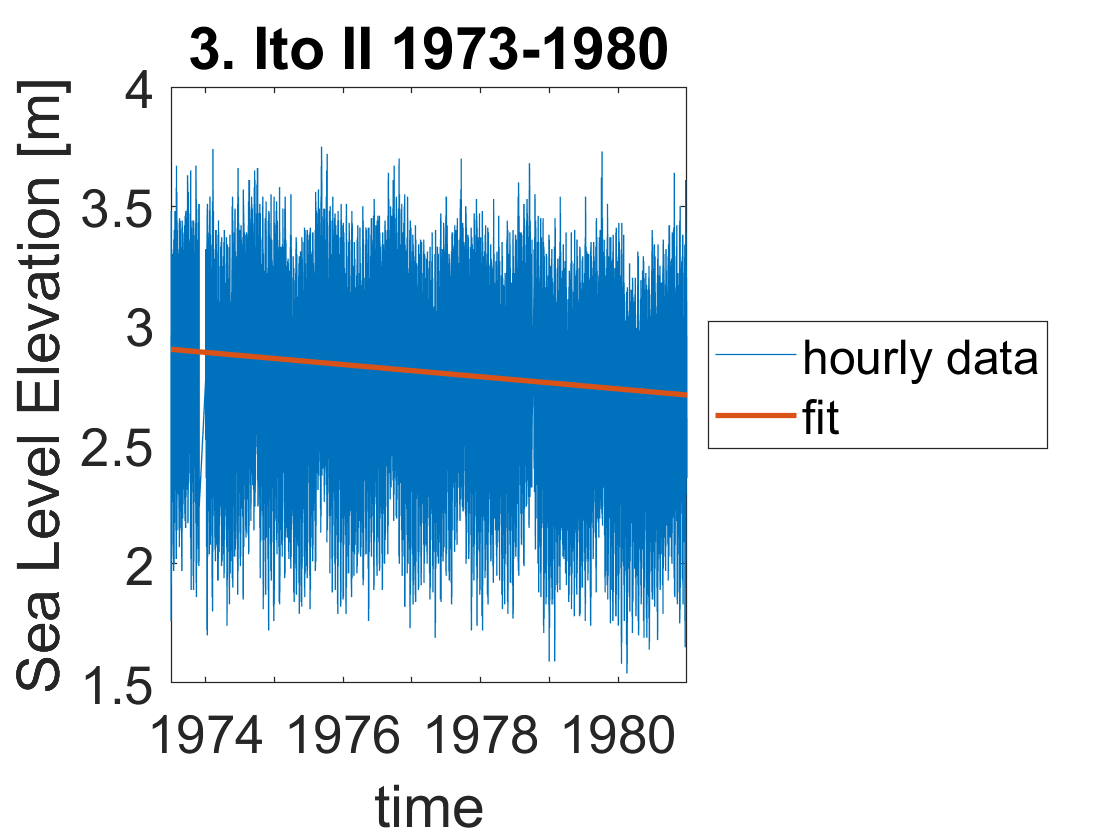

SLR for gauge 3. Ito II 1973-1980 from 07/01/1973 to 12/31/1980 is -2.5523 cm/y.


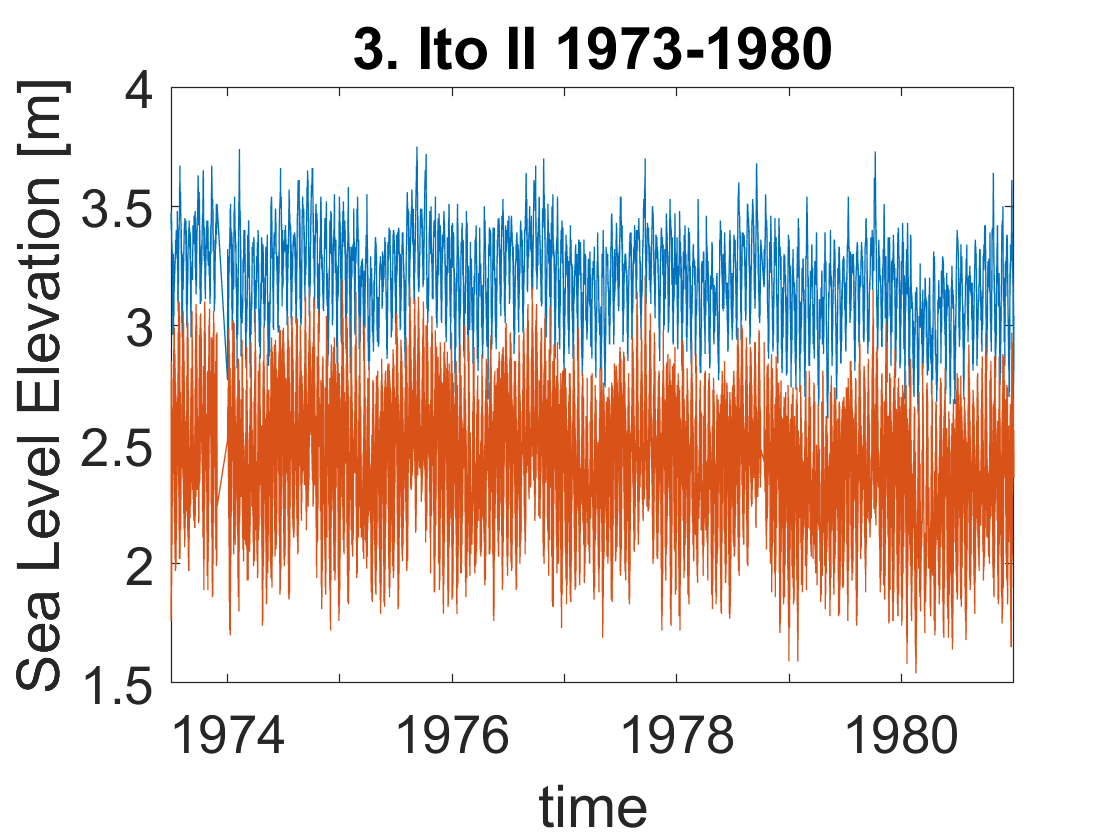

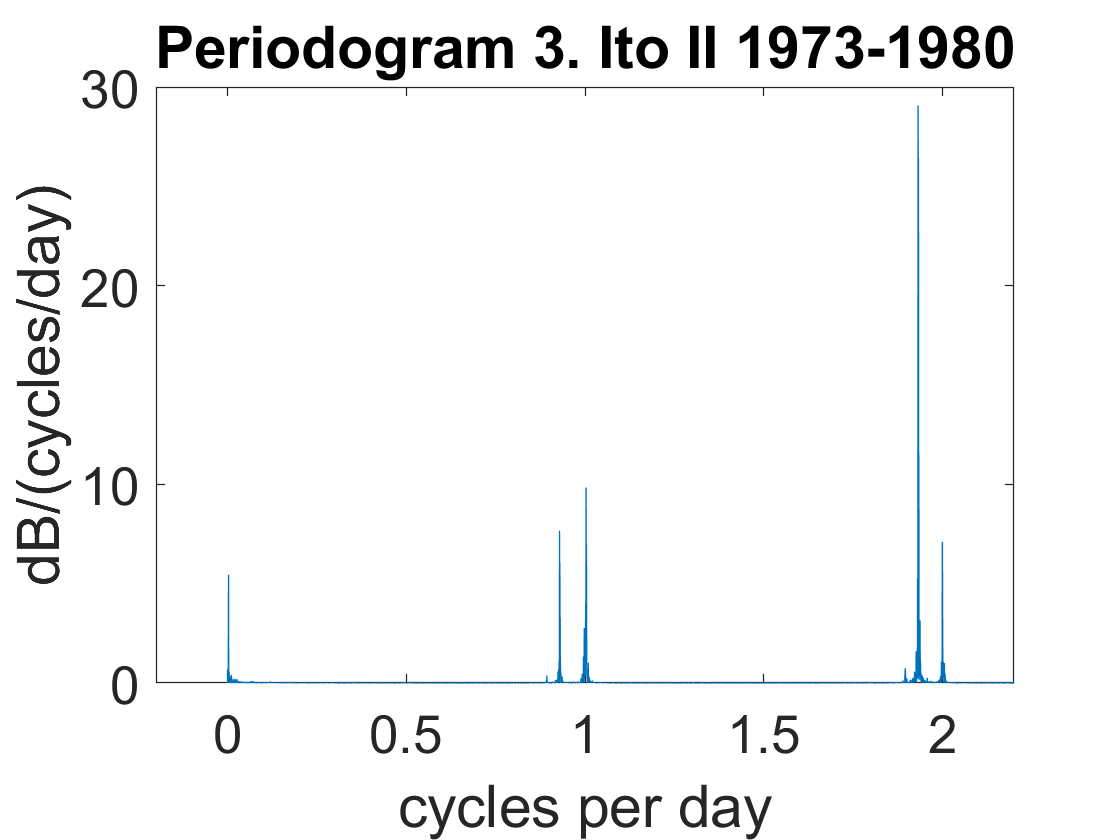

%3. Ito II 1973-1980
%datum is 5m

[regsol3a, peaks3a, mins3a, peaks_loc3a, mins_loc3a] = analyze(time3a, SL3a, '3. Ito II 1973-1980');

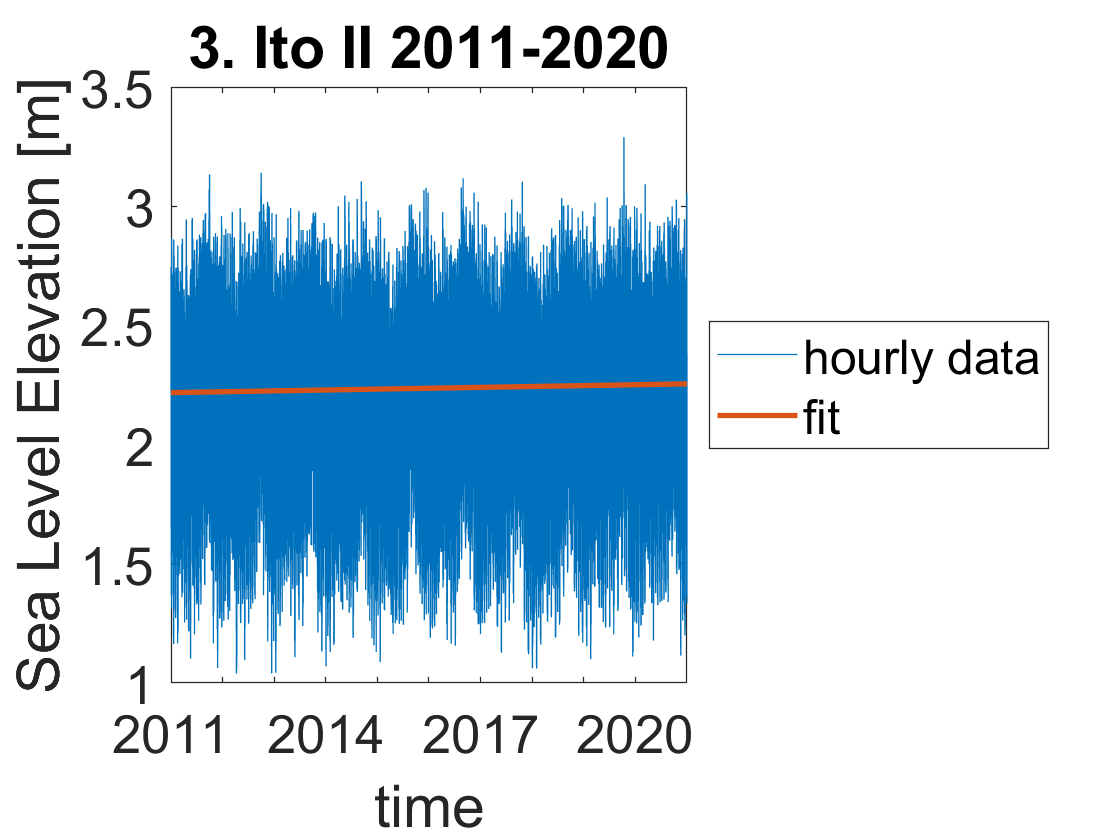

SLR for gauge 3. Ito II 2011-2020 from 01/01/2011 to 12/31/2020 is 0.36661 cm/y.


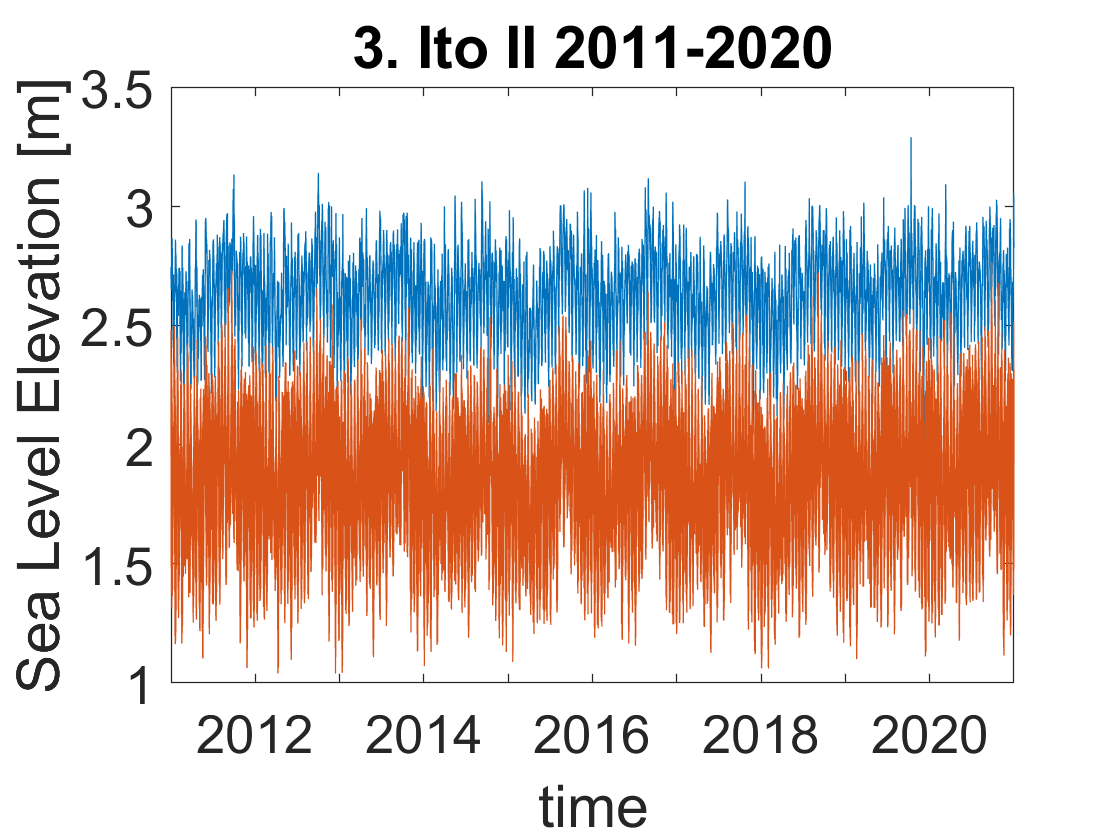

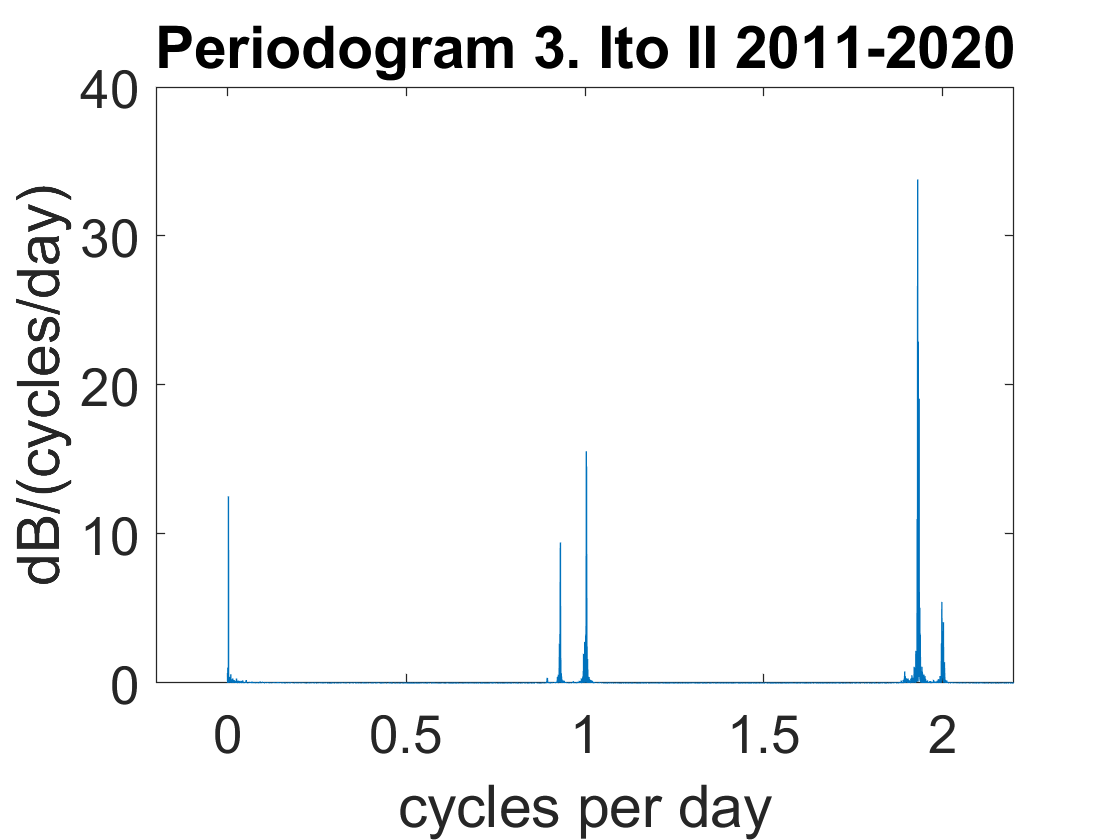

%3. Ito II 2011-2020 
%datum is

[regsol3b, peaks3b, mins3b, peaks_loc3b, mins_loc3b] = analyze(time3b, SL3b, '3. Ito II 2011-2020');

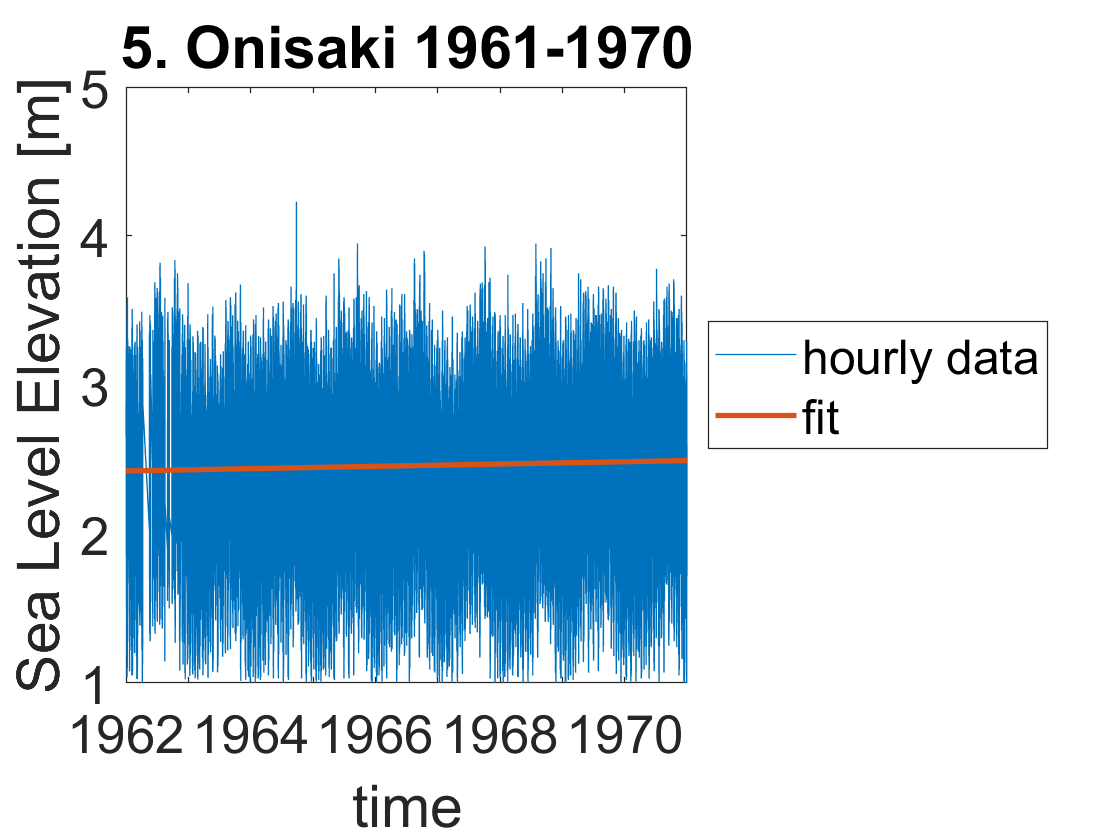

SLR for gauge 5. Onisaki 1961-1970 from 01/01/1962 to 12/30/1970 is 0.77611 cm/y.


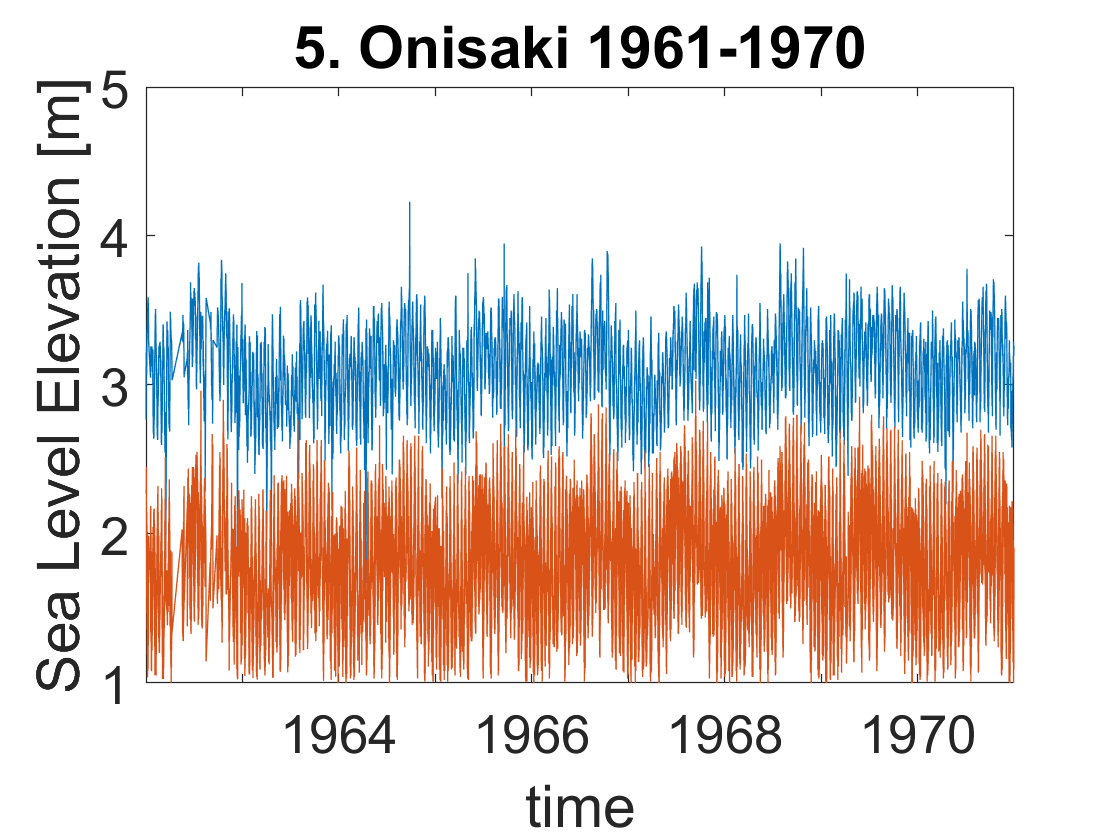

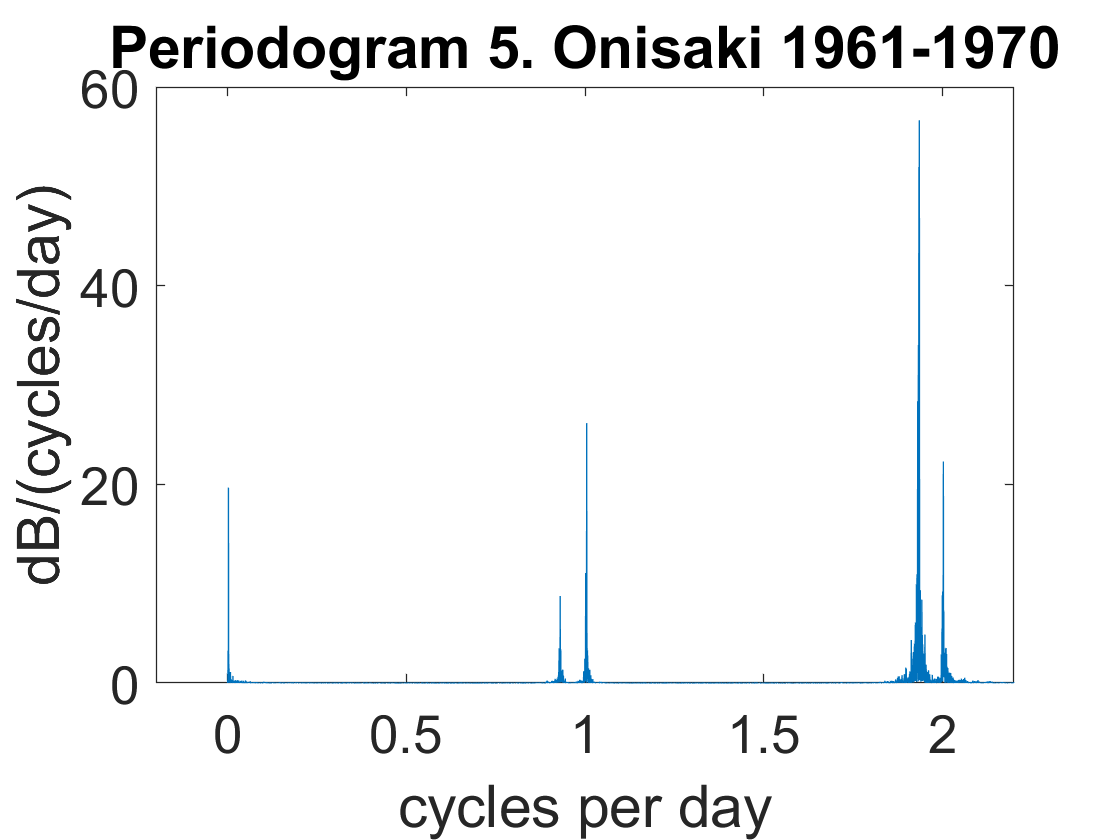

%5. Onisaki 1961-1970
%datum is 5m

[regsol5a, peaks5a, mins5a, peaks_loc5a, mins_loc5a] = analyze(time5a, SL5a, '5. Onisaki 1961-1970');

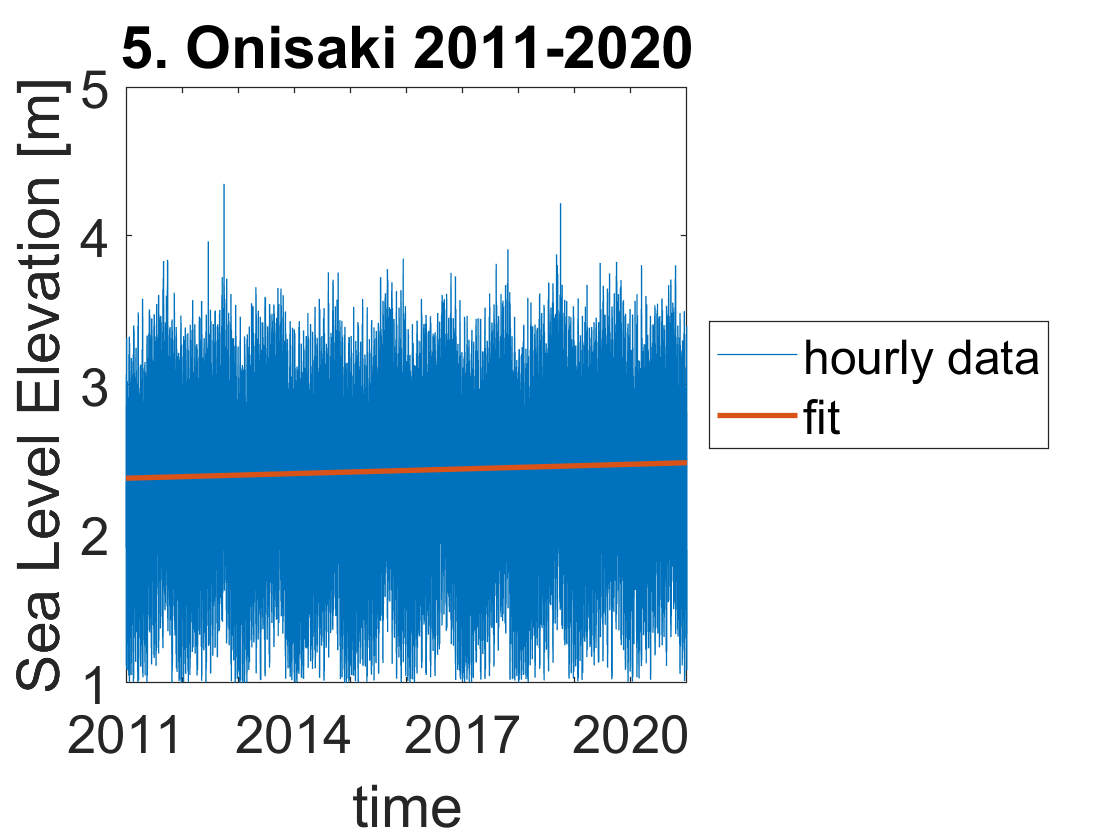

SLR for gauge 5. Onisaki 2011-2020 from 01/01/2011 to 12/31/2020 is 1.0394 cm/y.


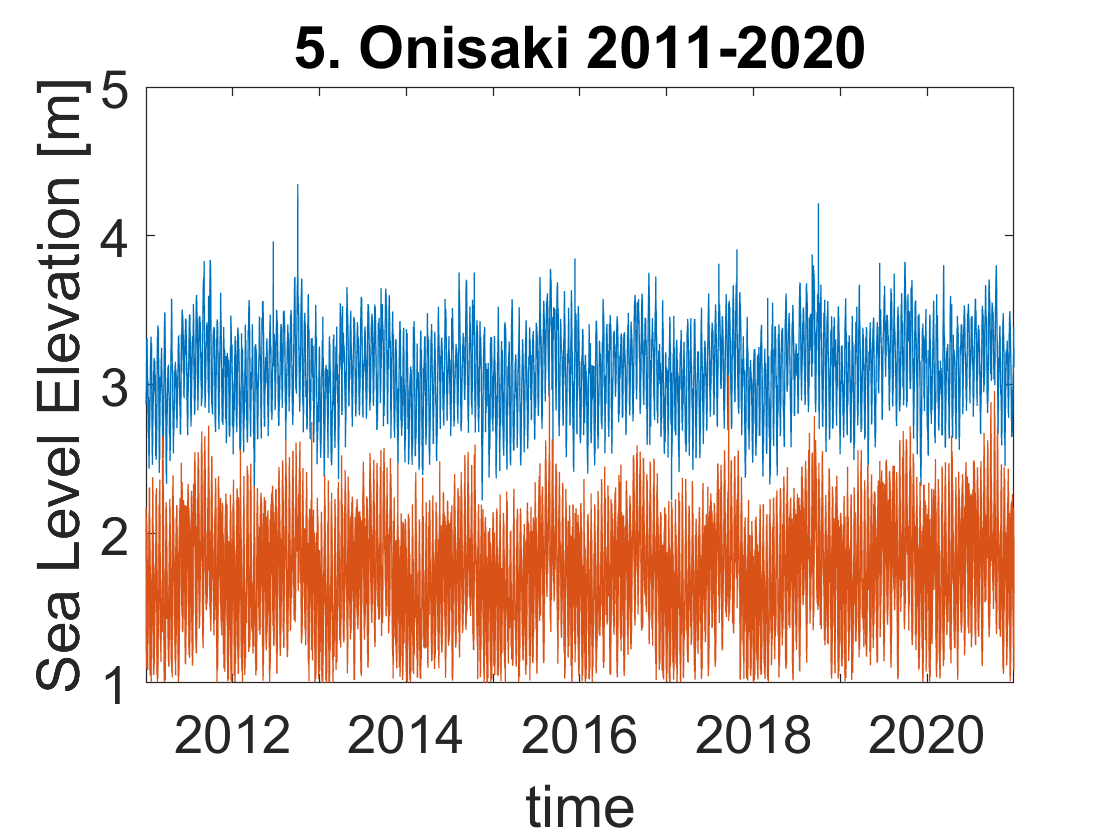

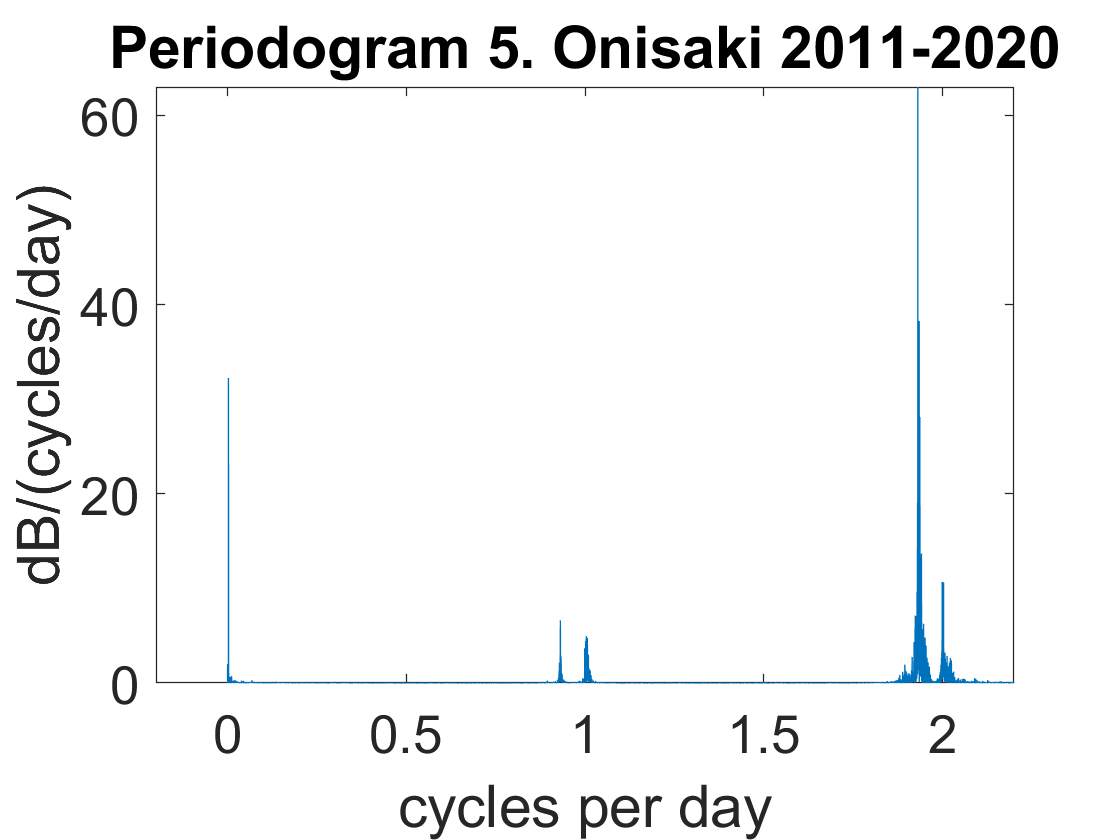

%5. Onisaki 2011-2020
%datum is 5m

[regsol5b, peaks5b, mins5b, peaks_loc5b, mins_loc5b] = analyze(time5b, SL5b, '5. Onisaki 2011-2020');

%Tidal range analysis
%smooth data for high tide
% peaks2a_smooth = smoothdata(peaks2a, 30);
% 
% plot(time2a(peaks_loc2a), peaks2a)
% plot(time2a(peaks_loc2a), peaks2a_smooth)
% 
% %obtain bounds for year 2 through year 6
% time_peaks2a = time2a(peaks_loc2a);
% time_peaks2a_bounded = time_peaks2a((time_peaks2a > (time_peaks2a(1) + years(1))) & (time_peaks2a < (time_peaks2a(1) + years(6))));
% peaks2a_smooth_bounded = peaks2a_smooth((time_peaks2a > (time_peaks2a(1) + years(1))) & (time_peaks2a < (time_peaks2a(1) + years(6))));
% 
% %find mins
% time_mins2a = time2a(mins_loc2a);
% 
% %loop through year 2 through year 5
% for i = 1:length(time_peaks2a_bounded)
%     %find indices of 1 years surrounding point
%     bounds_loc = (time_mins2a > (time_peaks2a_bounded(i) - years(1))) & (time_mins2a < (time_peaks2a_bounded(i) + years(1)));
%     
%     %subtract low tide with an average of 1 year around point
%     peaks2a_smooth(i) = mean(mins2a(bounds_loc));
% end
% 
% plot(time_peaks2a_bounded, peaks2a_smooth_bounded)

%averag everything and subtract
peaks_avg2a = mean(peaks2a);
mins_avg2a = mean(mins2a);
range2a = peaks_avg2a - mins_avg2a

range2a = 0.7098


peaks_avg2b = mean(peaks2b);
mins_avg2b = mean(mins2b);
range2b = peaks_avg2b - mins_avg2b

range2b = 0.8047


peaks_avg3a = mean(peaks3a);
mins_avg3a = mean(mins3a);
range3a = peaks_avg3a - mins_avg3a

range3a = 0.7997


peaks_avg3b = mean(peaks3b);
mins_avg3b = mean(mins3b);
range3b = peaks_avg3b - mins_avg3b

range3b = 0.7953


peaks_avg5a = mean(peaks5a);
mins_avg5a = mean(mins5a);
range5a = peaks_avg5a - mins_avg5a

range5a = 1.3273


peaks_avg5b = mean(peaks5b);
mins_avg5b = mean(mins5b);
range5b = peaks_avg5b - mins_avg5b

range5b = 1.3604


X = categorical({'Aburatsubo', 'Ito II', 'Onisaki'});
Y = [range2a, range3a, range5a; range2b, range3b, range5b];
h = bar(X, Y)

h =   1×2 Bar array:

    Bar    Bar


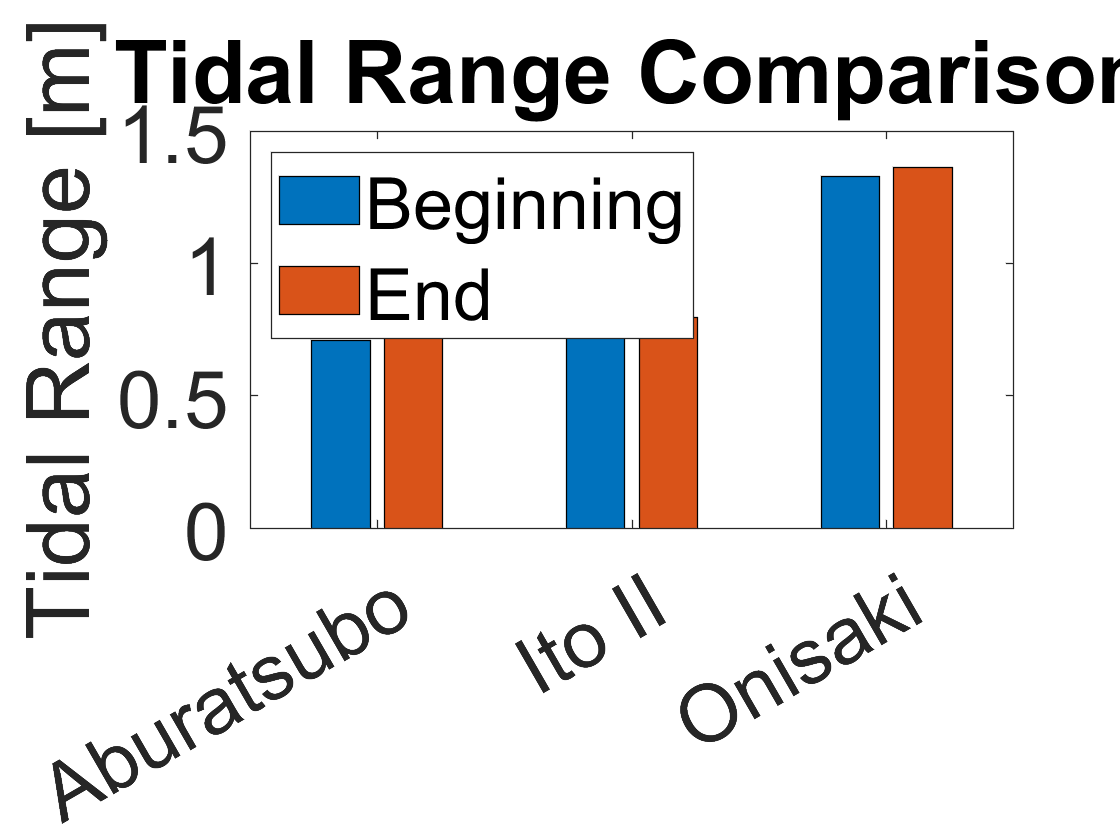

set(gca, 'fontsize', 30)
set(h, {'DisplayName'}, {'Beginning', 'End'}')
legend('location', 'northwest')
title('Tidal Range Comparison')
ylabel('Tidal Range [m]')

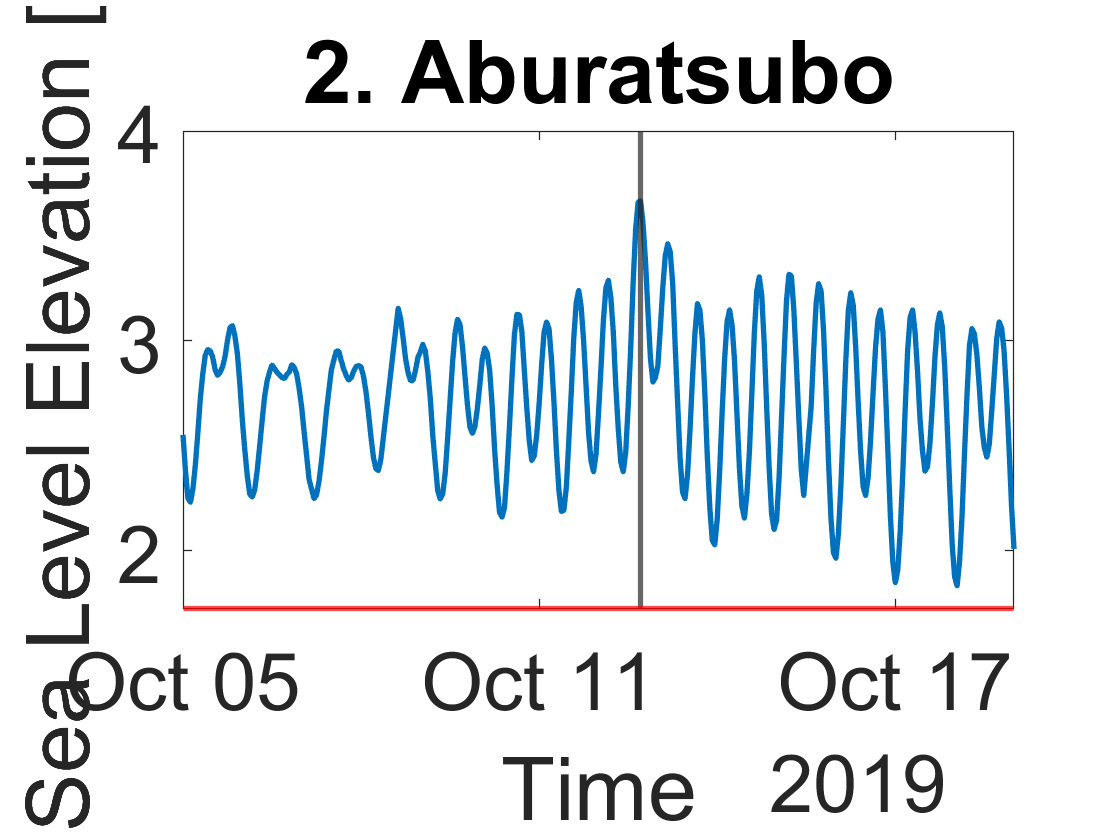

max_Hagibis2 = 3.6670

max_Hagibis_loc2 = 180

%Typhoon Hagibis
%landfall on Oct 12, 2019
%cut between Oct 5 and Oct 19
time_bounds = datetime(2019, 10, [5, 19]);

%average early time series for point of comparison
SL_avg2a = mean(SL2a);
SL_avg3a = mean(SL3a);
SL_avg5a = mean(SL5a);

%find time and SL for Hagibis
[max_Hagibis2, max_Hagibis_loc2] = hurricaneAnalysis(time_bounds, time2b, SL2b, SL_avg2a, '2. Aburatsubo')

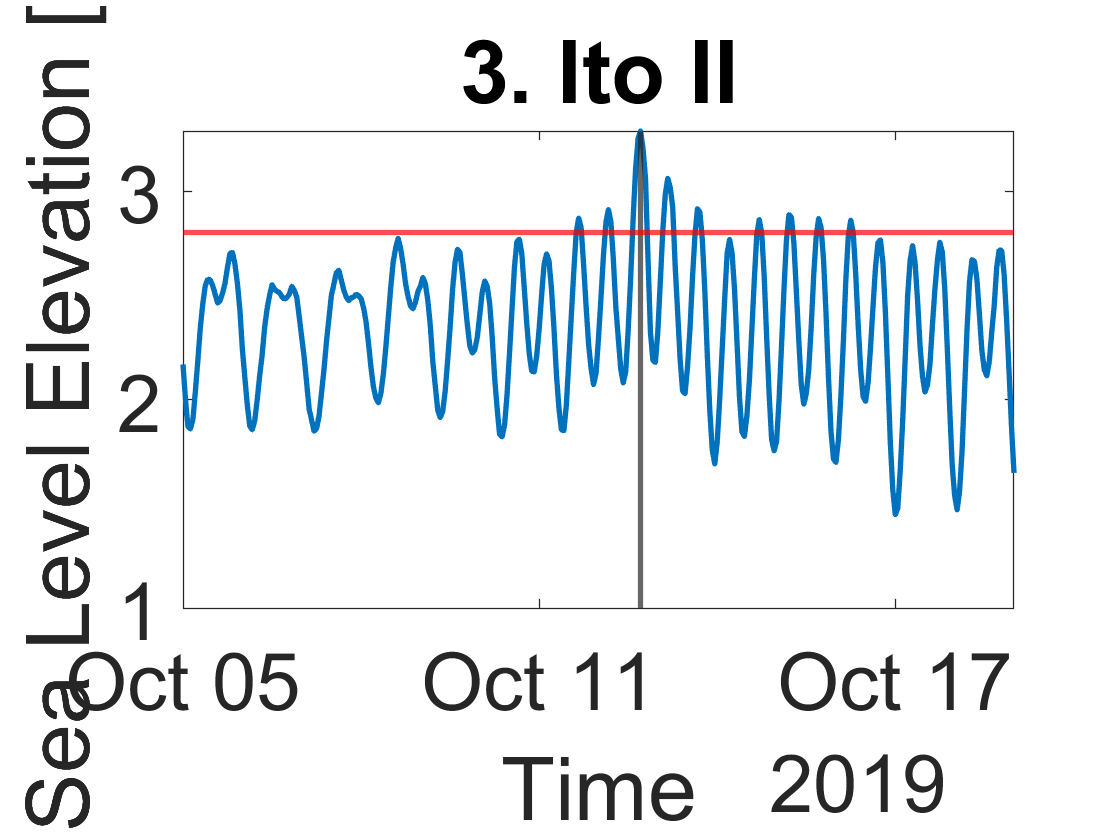

max_Hagibis3 = 3.2890

max_Hagibis_loc3 = 186

[max_Hagibis3, max_Hagibis_loc3] = hurricaneAnalysis(time_bounds, time3b, SL3b, SL_avg3a, '3. Ito II')

[max_Hagibis5, max_Hagibis_loc5] = hurricaneAnalysis(time_bounds, time5b, SL5b, SL_avg5a, '5. Onisaki')

max_Hagibis5 = 3.6100

max_Hagibis_loc5 = 186

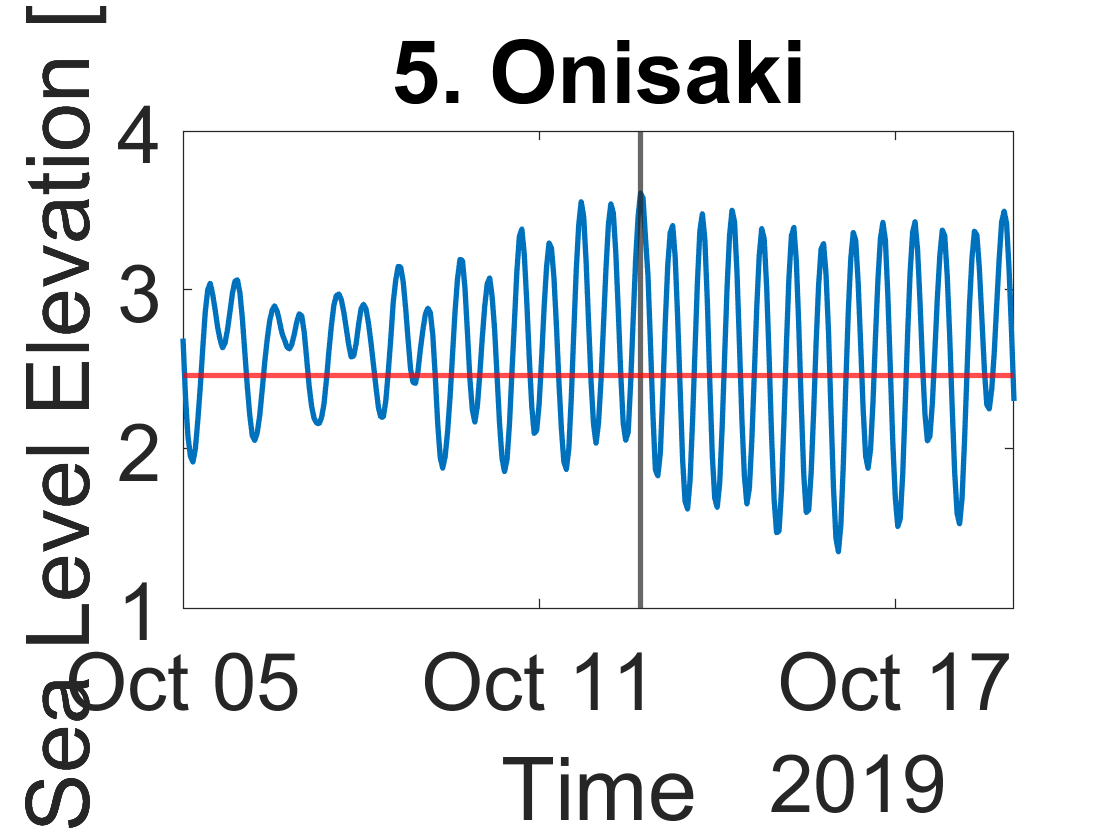


% figure
tiledlayout(3, 1)

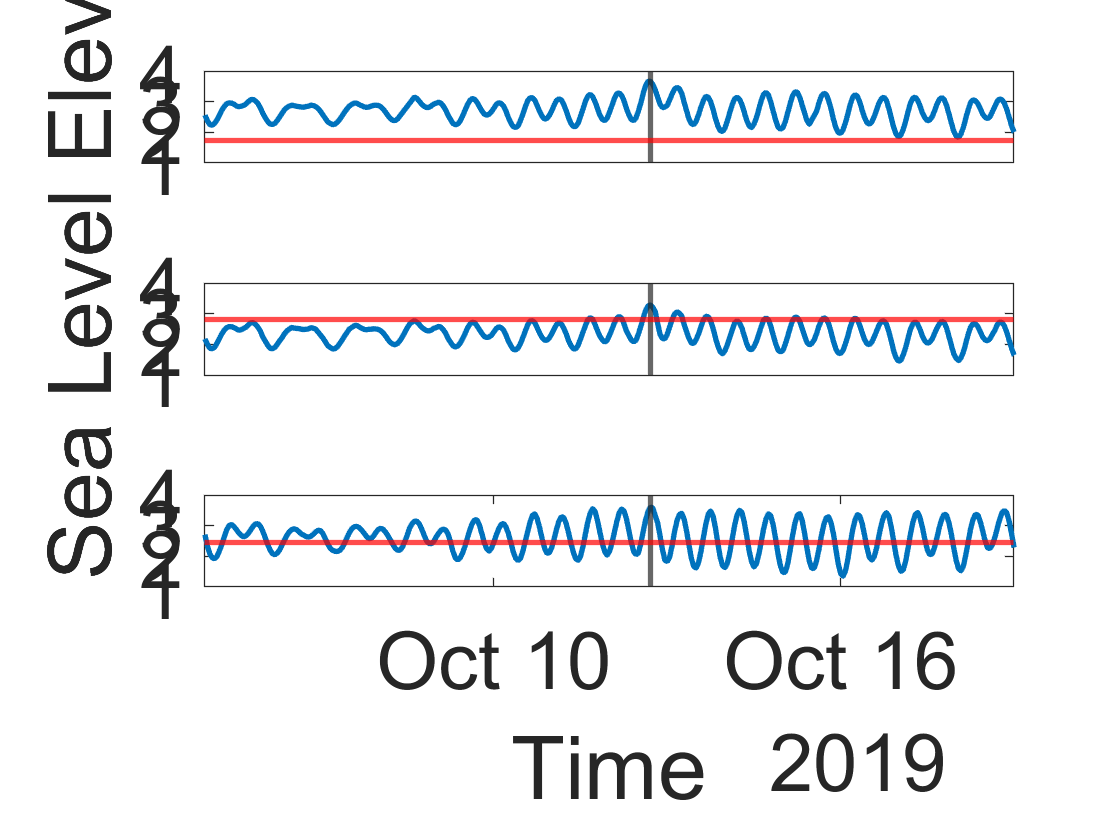

nexttile
plot(time2b, SL2b, 'LineWidth', 2)
xline(time2b(max_Hagibis2 == SL2b), 'linewidth', 2)
yline(SL_avg2a, 'LineWidth', 2, 'color', 'r')
set(gca, 'fontsize', 30)
xlim(time_bounds)
set(gca,'XTick',[])
ylabel('Sea Level Elevation [m]')
yticks([1, 2, 3, 4])
ylim([1, 4])

nexttile
plot(time3b, SL3b, 'LineWidth', 2)
xline(time3b(max_Hagibis3 == SL3b), 'linewidth', 2)
yline(SL_avg3a, 'LineWidth', 2, 'color', 'r')
set(gca, 'fontsize', 30)
set(gca,'XTick',[])
xlim(time_bounds)
yticks([1, 2, 3, 4])
ylim([1, 4])

nexttile
plot(time5b, SL5b, 'LineWidth', 2)
xline(time5b(max_Hagibis5 == SL5b), 'linewidth', 2)
yline(SL_avg5a, 'LineWidth', 2, 'color', 'r')
set(gca, 'fontsize', 30)
xlim(time_bounds)
xlabel('Time')
yticks([1, 2, 3, 4])
ylim([1, 4])

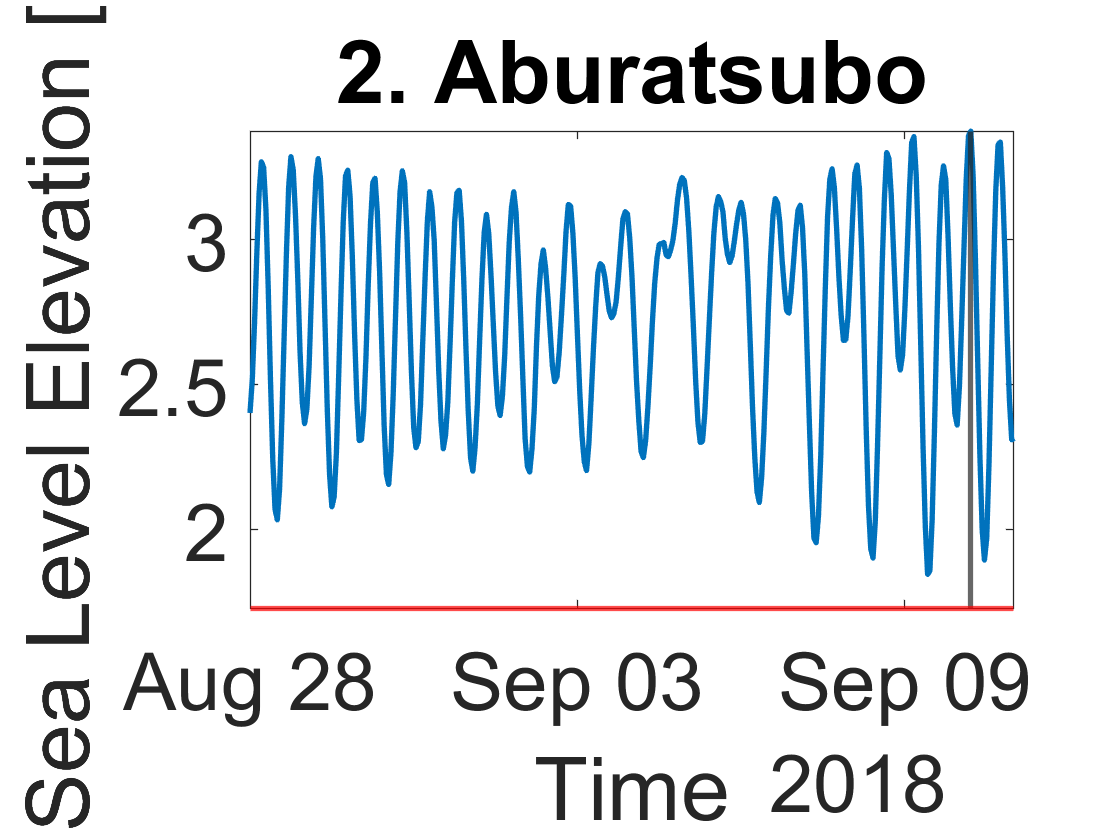

max_Jebi2 = 3.3740

max_Jebi_loc2 = 318

%Typhoon Jebi
%landfall on Sept 4, 2018
%cut between Aug 28 and Sept 11
time_bounds = datetime(2018, [8 9], [28 11]);

%average early time series for point of comparison
SL_avg2a = mean(SL2a);
SL_avg3a = mean(SL3a);
SL_avg5a = mean(SL5a);

%find time and SL for Hagibis
[max_Jebi2, max_Jebi_loc2] = hurricaneAnalysis(time_bounds, time2b, SL2b, SL_avg2a, '2. Aburatsubo')

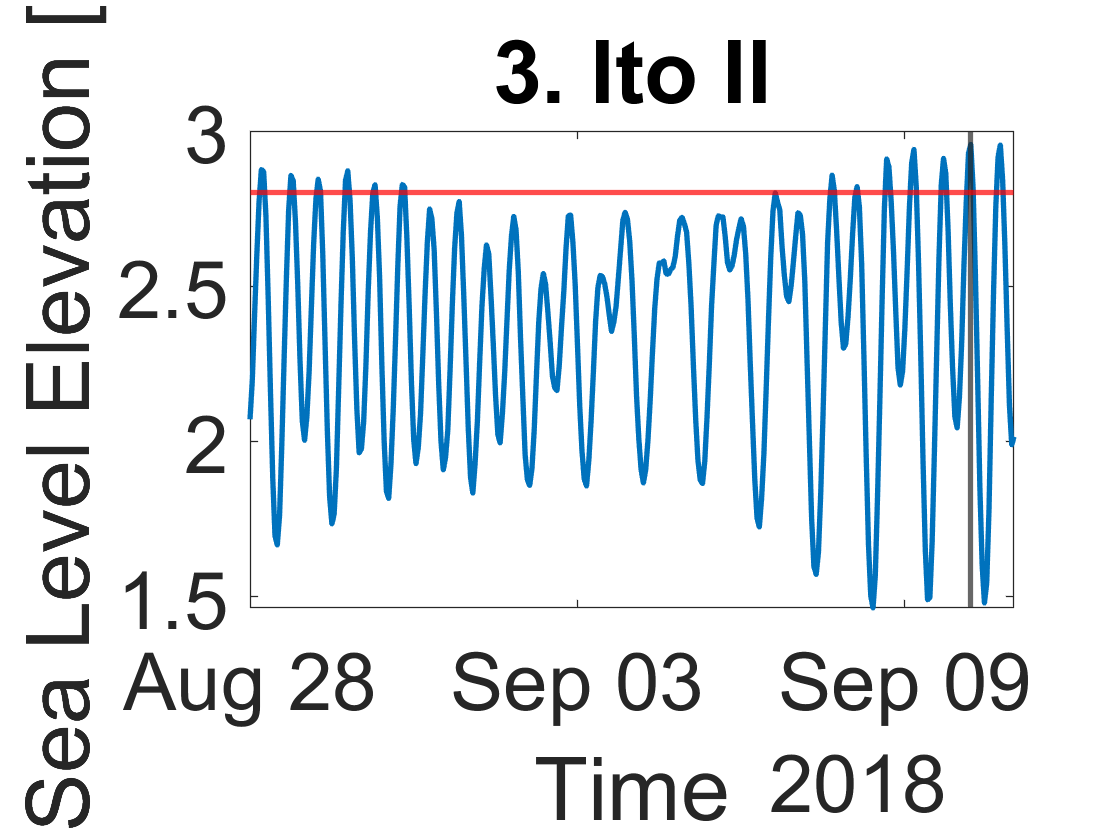

max_Jebi3 = 2.9570

max_Jebi_loc3 = 318

[max_Jebi3, max_Jebi_loc3] = hurricaneAnalysis(time_bounds, time3b, SL3b, SL_avg3a, '3. Ito II')

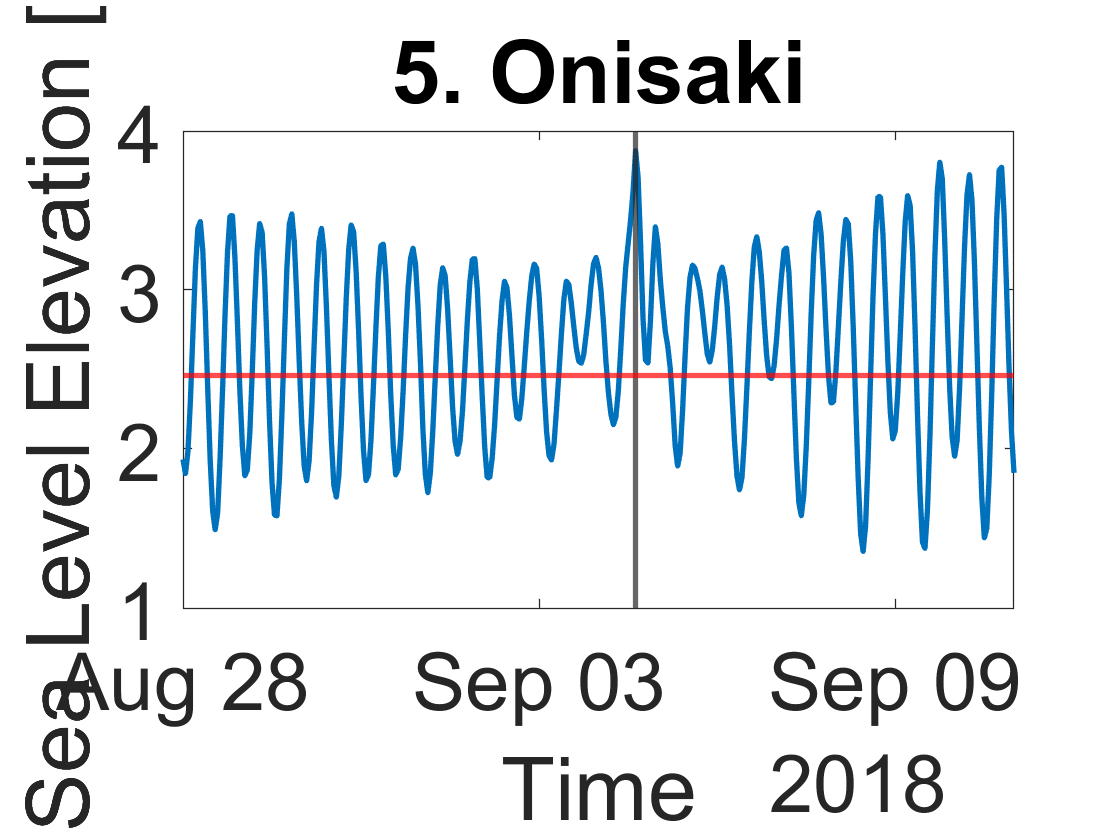

max_Jebi5 = 3.8770

max_Jebi_loc5 = 184

[max_Jebi5, max_Jebi_loc5] = hurricaneAnalysis(time_bounds, time5b, SL5b, SL_avg5a, '5. Onisaki')

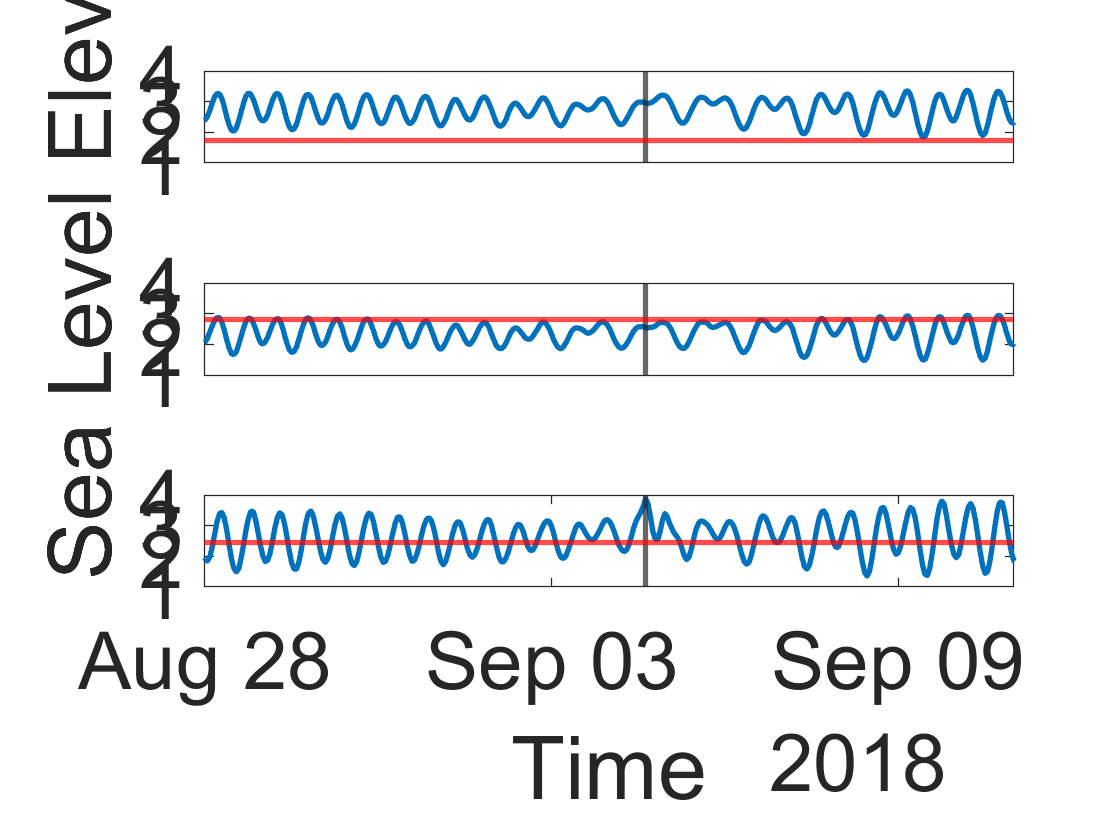


figure
tiledlayout(3, 1)
nexttile
plot(time2b, SL2b, 'LineWidth', 2)
xline(time5b(max_Jebi5 == SL5b), 'linewidth', 2)
yline(SL_avg2a, 'LineWidth', 2, 'color', 'r')
set(gca, 'fontsize', 30)
xlim(time_bounds)
set(gca,'XTick',[])
yticks([1, 2, 3, 4])
ylim([1, 4])
ylabel('Sea Level Elevation [m]')

nexttile
plot(time3b, SL3b, 'LineWidth', 2)
xline(time5b(max_Jebi5 == SL5b), 'linewidth', 2)
yline(SL_avg3a, 'LineWidth', 2, 'color', 'r')
set(gca, 'fontsize', 30)
set(gca,'XTick',[])
yticks([1, 2, 3, 4])
ylim([1, 4])
xlim(time_bounds)

nexttile
plot(time5b, SL5b, 'LineWidth', 2)
xline(time5b(max_Jebi5 == SL5b), 'linewidth', 2)
yline(SL_avg5a, 'LineWidth', 2, 'color', 'r')
set(gca, 'fontsize', 30)
xlim(time_bounds)
yticks([1, 2, 3, 4])
ylim([1, 4])
xlabel('Time')

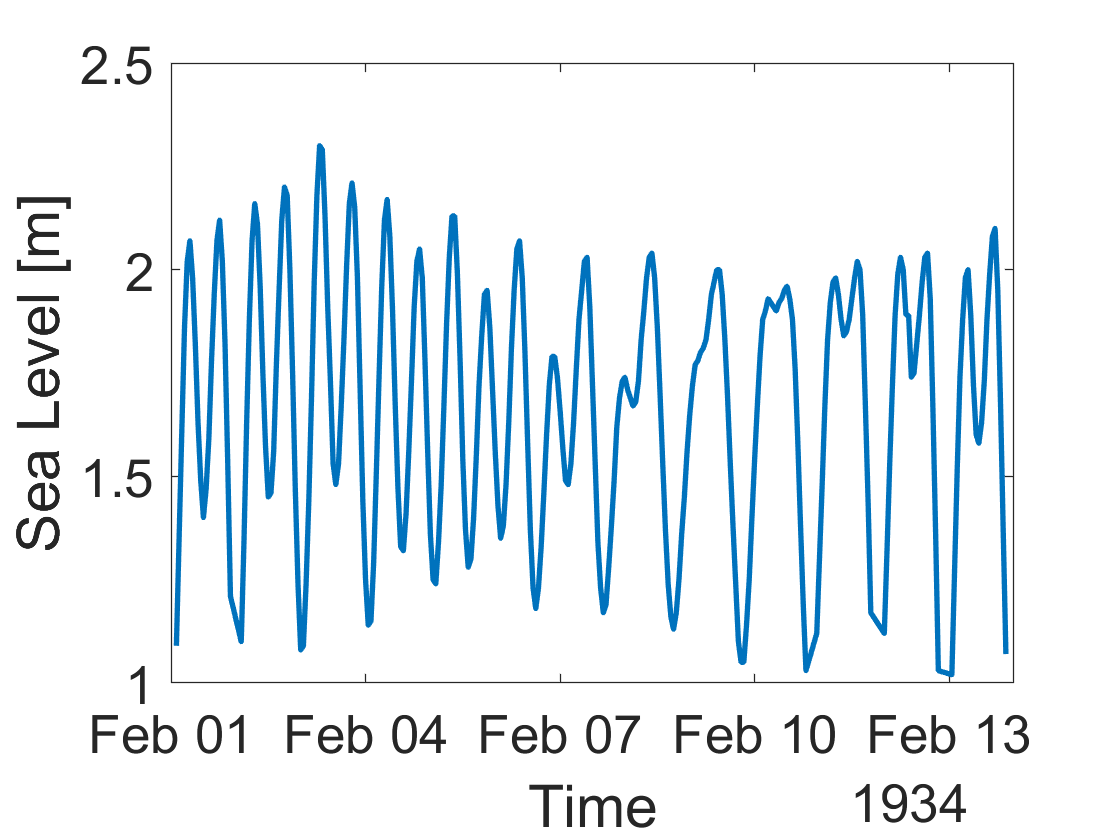

%zoom view of Aburatsubo for report
timeBounda = datetime(1934, 2, [1 14]);
timeBounda = time2a >= timeBounda(1) & time2a < timeBounda(2);
timeBoundb = datetime(2019, 2, [1 14]);
timeBoundb = time2b >= timeBoundb(1) & time2b < timeBoundb(2);

figure
plot(time2a(timeBounda), SL2a(timeBounda), 'LineWidth', 2)
set(gca, 'fontsize', 20)
xlabel('Time')
ylabel ('Sea Level [m]')

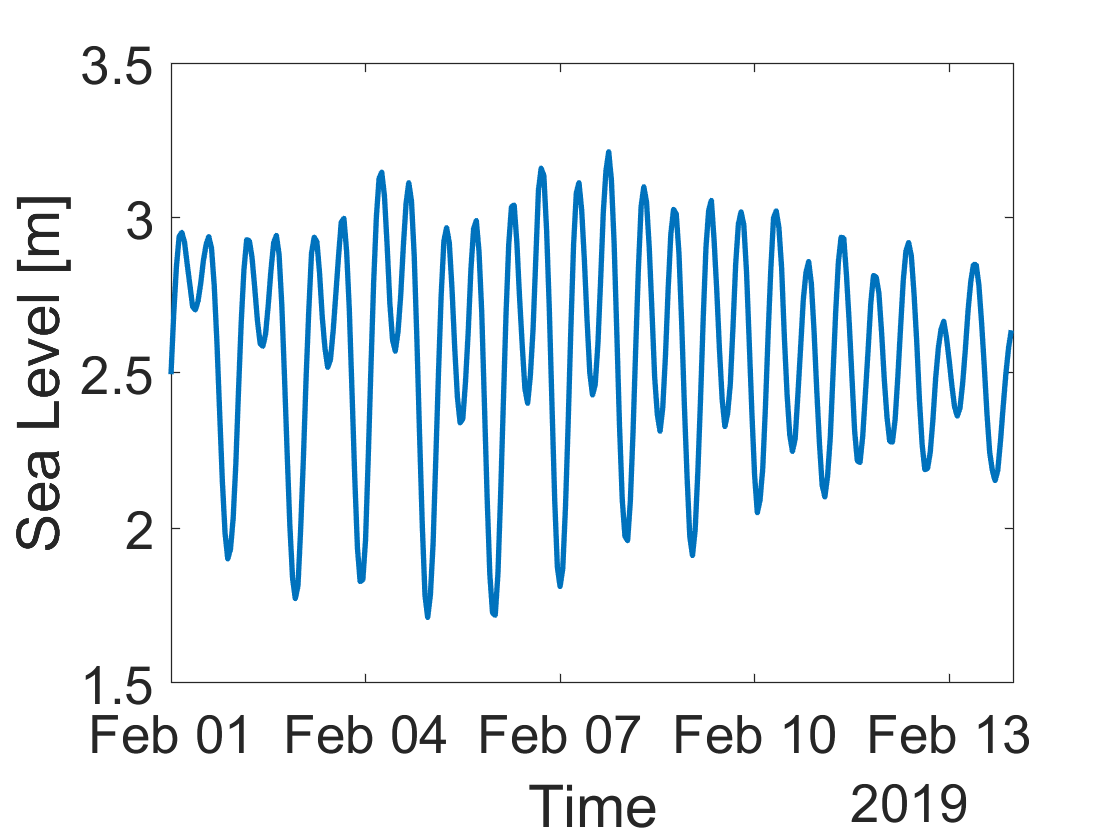


figure
plot(time2b(timeBoundb), SL2b(timeBoundb), 'LineWidth', 2)
set(gca, 'fontsize', 20)
xlabel('Time')
ylabel ('Sea Level [m]')

function [time, SL] = readGauge(path)
%read data
read = readtable(path);
raw = table2array(read(:, 1));
raw = raw(~cellfun('isempty',raw)); 

time = num2cell(ones(size(raw)));
% fp = num2cell(ones(size(raw)));
level = num2cell(ones(size(raw)));

%take out date and SL data
for i = 1:length(raw)
    strings = split(raw{i}, ' ');
    time(i) = strcat(strings(2), strings(3));
%     fp(i) = strings(11);
    level(i) = strings(5);
end

%convert to double
% fp = str2double(fp);
level = str2double(level);

%remove null SL and NaN
null_ind = level == -999;
time(null_ind) = [];
% fp(null_ind) = [];
level(null_ind) = [];
time(isnan(level)) = [];
level(isnan(level)) = [];

%datetime
time = datetime(time, "InputFormat", 'yyyy/MM/ddHH');

%find SL = fixed point + level
SL = level;
%convert SL and level to m
SL = SL/1000;
% level = level/1000
end

function [regsol, peaks, mins, loc_peaks, loc_mins] = analyze(time, SL, label)
%performs all necessary analysis

%%linear regression
num = datenum(time);
A(:, 1) = (num - num(1))/365;
A(:, 2) = 1;
regsol = A\SL;
linreg = regsol(1).*A(:, 1) + regsol(2);

figure
plot(time, SL)
hold on
plot(time, linreg, 'LineWidth', 2)
set(gca, 'fontsize', 20)
xlabel('time')
ylabel('Sea Level Elevation [m]')
title(label)
legend('hourly data', 'fit', 'location', 'eastoutside')
hold off

%slope of regression [cm/y]
out = 'mm/dd/yyyy';
printStr = ['SLR for gauge ', label, ' from ', datestr(time(1), out) ,' to ', datestr(time(end), out), ' is ', num2str(regsol(1)*100), ' cm/y.'];
disp(printStr)

%%no trend graph
%normalize data from trend
SL_noSLR = SL - linreg;
%find peaks and minimums
[peaks, loc_peaks] = findpeaks(SL);
[mins, loc_mins] = findpeaks(SL*-1);

%actual mins are just at the indices
mins = SL(loc_mins);

figure
plot(time(loc_peaks), peaks)
hold on
plot(time(loc_mins), mins)
set(gca, 'fontsize', 20)
xlabel('time')
ylabel('Sea Level Elevation [m]')
title(label)
hold off

%%periodogram
[pxx, f] = periodogram(SL_noSLR, [], [], 24);

figure
plot(f, pxx)
set(gca, 'fontsize', 20)
title(['Periodogram ' label])
xlabel('cycles per day')
xlim([-0.2, 2.2])
ylabel('dB/(cycles/day)')
end

function [date_beg, SL_beg, date_end, SL_end] = cleave(inDate, inSL, separator)
%returns data from beginning to separator date, inclusive, and the rest
ind = inDate <= separator;

%returns beginning
date_beg = inDate(ind);
SL_beg = inSL(ind);

%returns end
date_end = inDate(~ind);
SL_end = inSL(~ind);
end

function [max_height, max_loc] = hurricaneAnalysis(time_bounds, time, SL, earlySL_avg, label)
time_hurr = (time >= time_bounds(1)) & (time <= time_bounds(2));
SL_hurr = SL(time_hurr);
time_hurr = time(time_hurr);

[max_height, max_loc] = max(SL_hurr);

figure
plot(time_hurr, SL_hurr, 'LineWidth', 2)
xline(time_hurr(max_loc), 'linewidth', 2)
yline(earlySL_avg, 'LineWidth', 2, 'color', 'r')
set(gca, 'fontsize', 30)
xlabel('Time')
xlim(time_bounds)
ylabel('Sea Level Elevation [m]')
title(label)
end